# Assignment 1

## Question 1

% pdf of simulation 
data_1=stabgen(1000000,1.7,-0.4,2,0.3,1);
int1=(max(data_1)-min(data_1))/1000000;
[pdf1_1,x1_1]=ksdensity(data,(min(data):int1:max(data_1)),'Function','pdf');

% pdf of true density 
x1_2= -8:.04:8;
pdf1_2=asymstab(x1_2,1.7,-0.4,2,0.3);

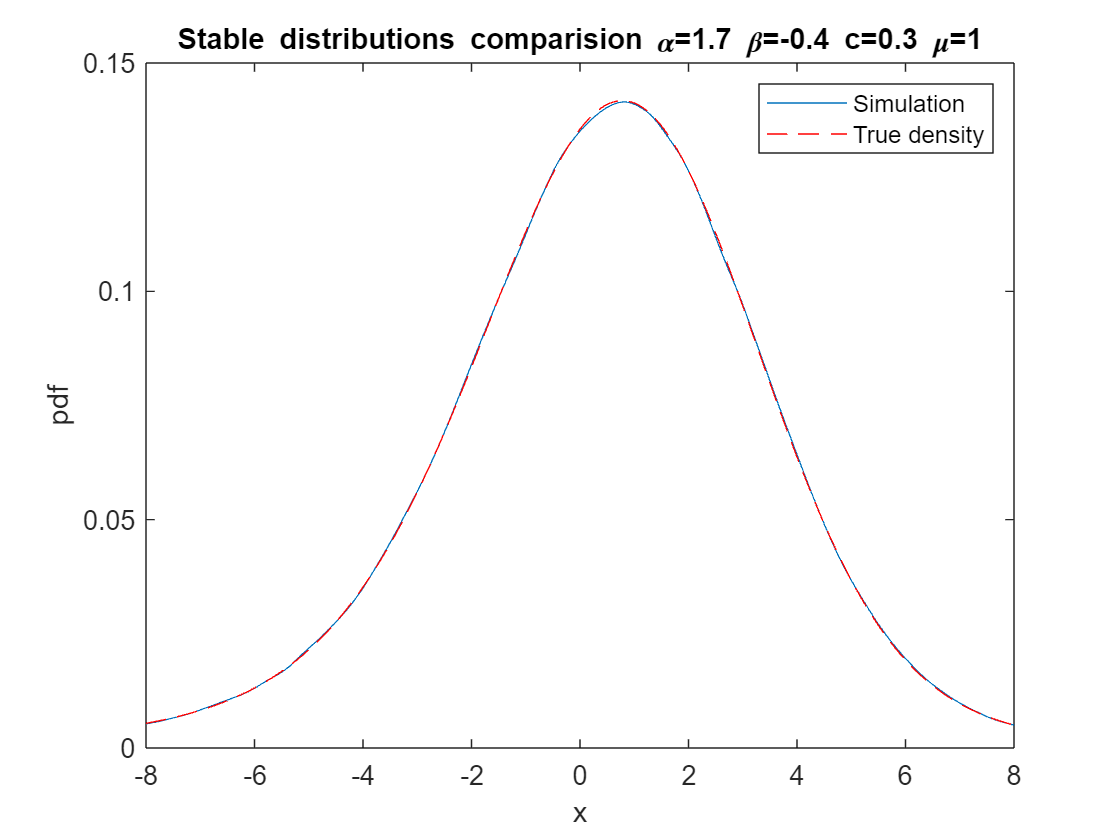

figure
plot(x1_1,pdf1_1)
hold on;
plot(x1_2,pdf1_2, 'r--')
xlim([-8 8]);
title('Stable distributions comparision \alpha=1.7 \beta=-0.4 c=0.3 \mu=1')
legend('Simulation','True density')
xlabel('x') 
ylabel('pdf') 
hold off;

## Question 2

% pdf of simulation
data_2=sum_stabgen(1000000,1.7,-0.4,2,-0.5,1.7,-0.5,1,0.3,1,2);
int2=(max(data_2)-min(data_2))/1000000;
[pdf2_1,x2_1]=ksdensity(data,(min(data_2):int2:max(data_2)),'Function','pdf');

% pdf of true density
x2_2 = -8:.04:8;
pdf2_2 = sum_asymstab(x2_2,1.7,-0.4,2,-0.5,1.7,-0.5,1,0.3);



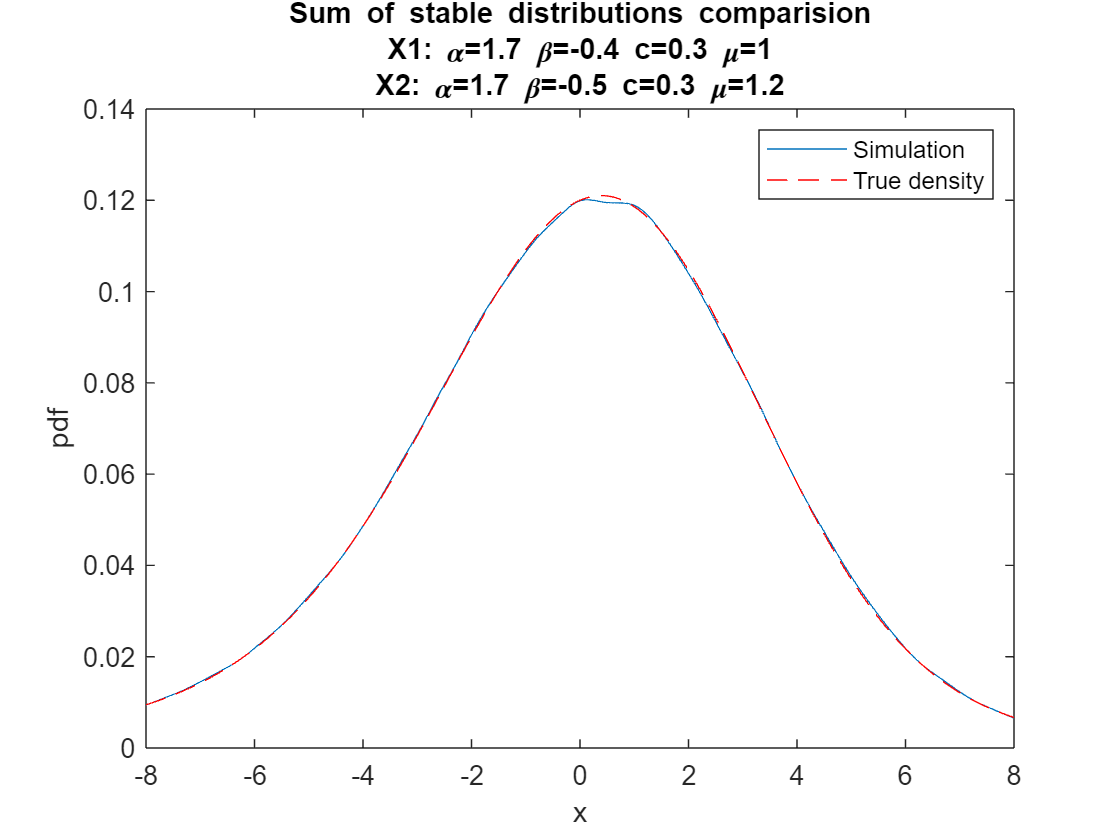

figure
plot(x2_1,pdf2_1);
hold on;
plot(x2_2,pdf2_2,'r--');
xlim([-8 8]);
title("Sum of stable distributions comparision"+newline+"X1: \alpha=1.7 \beta=-0.4 c=0.3 \mu=1"+newline+ "X2: \alpha=1.7 \beta=-0.5 c=0.3 \mu=1.2")
legend('Simulation','True density')
xlabel('x') 
ylabel('pdf') 
hold off;

## Question 3